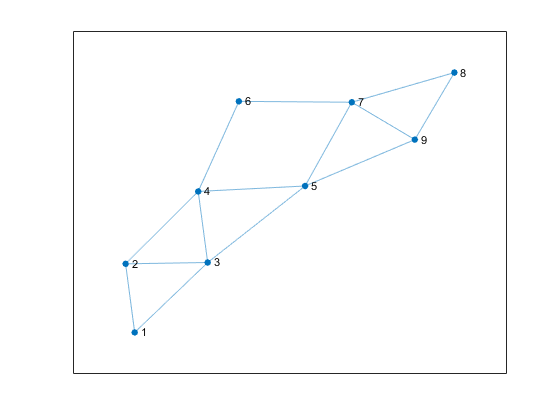

global L S signS
% Code Matlab mo phong he dong thuan voi do thi G1
%A=zeros(9,9);
R1 = [cos(pi/4) -sin(pi/4);
      sin(pi/4) cos(pi/4)];
R0 = [cos(pi/3) -sin(pi/3);
      sin(pi/3) cos(pi/3)];
R2 = [cos(2*pi/3) -sin(2*pi/3);
      sin(2*pi/3) cos(2*pi/3)];
R3 = [cos(4*pi/3) -sin(4*pi/3);
      sin(4*pi/3) cos(4*pi/3)];
r1 = [-1;0];
r2 = R2*r1;
r3 = R3*r1;
S1 =  [R1 r1;0 0 1];
S2 =  [R1 r2;0 0 1];
S3 =  [R1 r3;0 0 1];
S4 =  [R1*R2 -r1;0 0 -1];
S5 =  [R1*R2 -r2;0 0 -1];
S6 =  [R1*R2 -r3;0 0 -1];
S7 =  [R1*R2^2 r1;0 0 1];
S8 =  [R1*R2^2 r2;0 0 1];
S9 =  [R1*R2^2 r3;0 0 1];

S = blkdiag(S1,S2,S3,S4,S5,S6,S7,S8,S9);

signS = blkdiag(eye(3),-eye(3),eye(3)); 
sgnS = signS*ones(9,1);
% X = zeros(3,3);
% for i=1:9
%     X = X + inv(S(3*i-2:3*i,3*i-2:3*i))*sgnS(i);
% end

[V,D] = eig(S*kron(signS,eye(3)));
n = 9;
m = 14;
d = 3;

s = [1 1 2 2 3 3 4 4 5 5 6 7 7 8];
t = [2 3 3 4 4 5 5 6 7 9 7 8 9 9];
G = graph(s,t);
H = incidence(G)'*eye(9);
figure
plot(G)

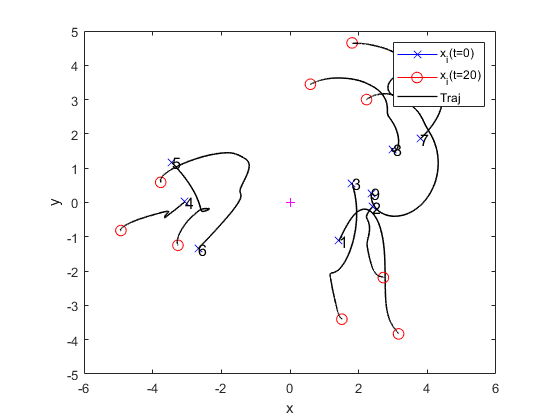

A12 = [1 sqrt(3)/2 0; sqrt(3)/2 1 0; 0 0 0];
A13 = [0  0 0; 0 1 0; 0 0 1];
A23 = [2  1 0; 1 1 0; 0 0 1];
A24 = A13; A34 = A13;
A35 = [1 0 0; 0 0 0; 0 0 0];
A45 = diag([1, 2, 3]);
A78 = eye(3);
A79 = eye(3);
A89 = ones(3,3);
A46 = A89;
A67 = A12;
A57 = A35;
A59 = A13;
W = blkdiag(A12,A13,A23,A24,A34,A35,A45,A46,A57,A59,A67,A78,A79,A89);

Hbar = kron(H,eye(d));
L = Hbar'*W*Hbar;
% 
% L=laplacian(G)*eye(9);

% Initial condition
rng(2);
x0 = 3*(rand(27,1)-0.5);

for i=1:9
    x0(3*i-2:3*i-1,1) = sgnS(i)*[3;0]+4*(rand(2,1)-0.5);
    x0(3*i,1) = sgnS(i);
end
% xo = [0;0;0];
% for i = 1:9
%     xo = xo + sgnS(i)*x0(3*i-2:3*i);
% end
% xo = inv(X)*xo
% 
% Solve MSC system using ode45
% load('simSnowFlake.mat')
[t,x] = ode45(@control_law,[0:0.01:20],x0);
t_end = length(t);
% Bieu dien tren do thi
str3 ='#C0C0C0';
color3 = sscanf(str3(2:end),'%2x%2x%2x',[1 3])/255;

figure
hold on;
for i=1:9
    plot(x(1,3*i-2)',x(1,3*i-1)',"Marker","x","Color","b","MarkerSize",8);
    plot(x(t_end,3*i-2)',x(t_end,3*i-1)',"Marker","o","Color","r","MarkerSize",8);
    plot(x(:,3*i-2)',x(:,3*i-1)','LineWidth',1,"Color","k","LineStyle","-");
    text((x(1,3*i-2))',(x(1,3*i-1))',num2str(i),"Color",'k',"FontSize",12);
end

plot(0,0,'Marker',"+","Color","m")

axis equal
xlim([-6,6])
ylim([-5,5])
box on
xlabel x
ylabel y
legend({'x_i(t=0)','x_i(t=20)','Traj'})
grid off

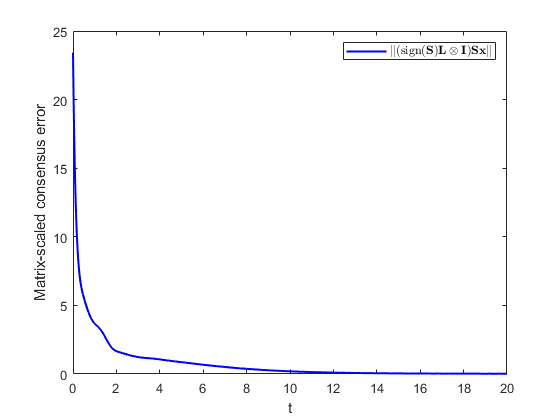


err = zeros(1,length(t));

for i = 1:length(t)
    err(1,i) = norm(kron(signS,eye(3))*L*S*x(i,:)');
end

figure
hold on
plot(t,err,'-b','LineWidth',1.5)
xlabel('t')
ylabel('Matrix-scaled consensus error')
legend('$\|({\rm sign}(\mathbf{S})\mathbf{L}\otimes\mathbf{I})\mathbf{S}\mathbf{x}\|$',"interpreter","latex")
box on

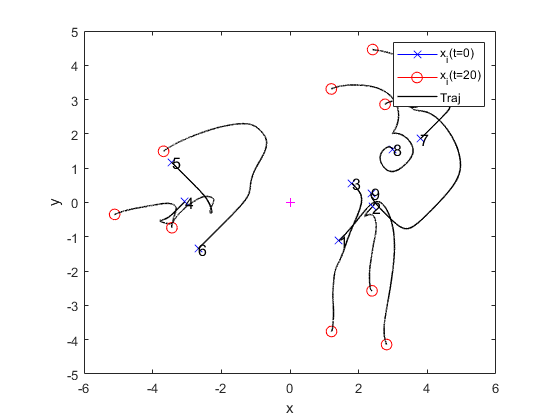


[t,x] = ode45(@control_law1,[0:0.01:60],x0);
t_end = length(t);
% Bieu dien tren do thi
str3 ='#C0C0C0';
color3 = sscanf(str3(2:end),'%2x%2x%2x',[1 3])/255;

figure
hold on;
for i=1:9
    plot(x(1,3*i-2)',x(1,3*i-1)',"Marker","x","Color","b","MarkerSize",8);
    plot(x(t_end,3*i-2)',x(t_end,3*i-1)',"Marker","o","Color","r","MarkerSize",8);
    plot(x(:,3*i-2)',x(:,3*i-1)','LineWidth',1,"Color","k","LineStyle","-");
    text((x(1,3*i-2))',(x(1,3*i-1))',num2str(i),"Color",'k',"FontSize",12);
end

plot(0,0,'Marker',"+","Color","m")

axis equal
xlim([-6,6])
ylim([-5,5])
box on
xlabel x
ylabel y
legend({'x_i(t=0)','x_i(t=60)','Traj'})
grid off

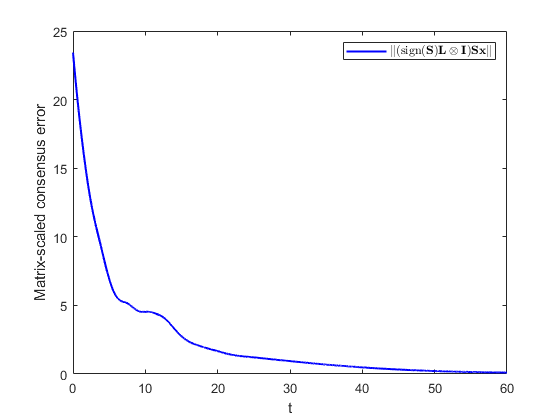


err = zeros(1,length(t));

for i = 1:length(t)
    err(1,i) = norm(kron(signS,eye(3))*L*S*x(i,:)');
end

figure
hold on
plot(t,err,'-b','LineWidth',1.5)
xlabel('t')
ylabel('Matrix-scaled consensus error')
legend('$\|({\rm sign}(\mathbf{S})\mathbf{L}\otimes\mathbf{I})\mathbf{S}\mathbf{x}\|$',"interpreter","latex")
box on

function dpdt = control_law(t,p)
    global L S signS
    dpdt = -kron(signS,eye(3))*L*S*p;
end

function dpdt = control_law1(t,p)
    global L S signS
    dpdt = -1/4*tanh(kron(signS,eye(3))*L*S*p);
end